## Example script for performing Fourier Transforms

First to load an example file (only run this bit once)

addpath(genpath("../../"));

load("C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s01_ex01_s01.mat");

Then to actually perform computations

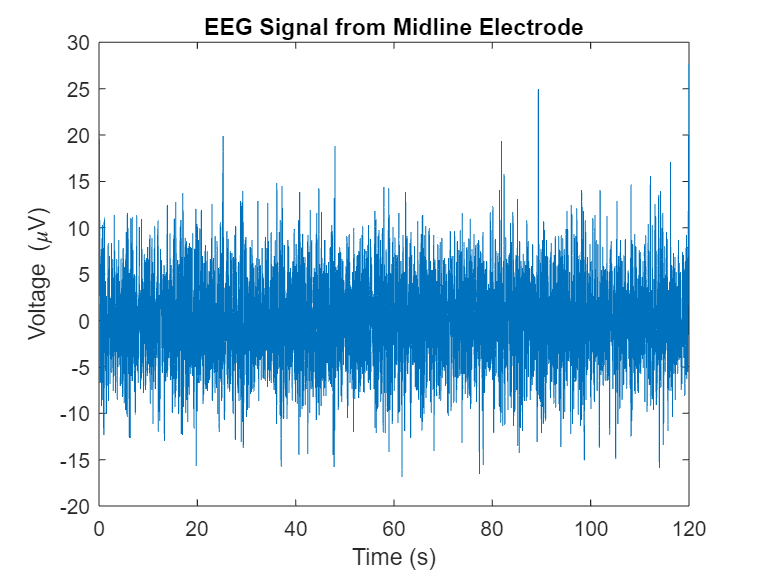

fs = 200;   % Sampling Frequency (Hz)
L = 120;    % Length of signal (ms)
T = 1/fs;   % Period
t = 0:T:L;  % Time vector

fig1 = figure;

plot(t(1:end - 1), Cz); % Plotting midline electrode readings against time
title("EEG Signal from Midline Electrode");
xlabel("Time (s)");
ylabel("Voltage (\muV)");

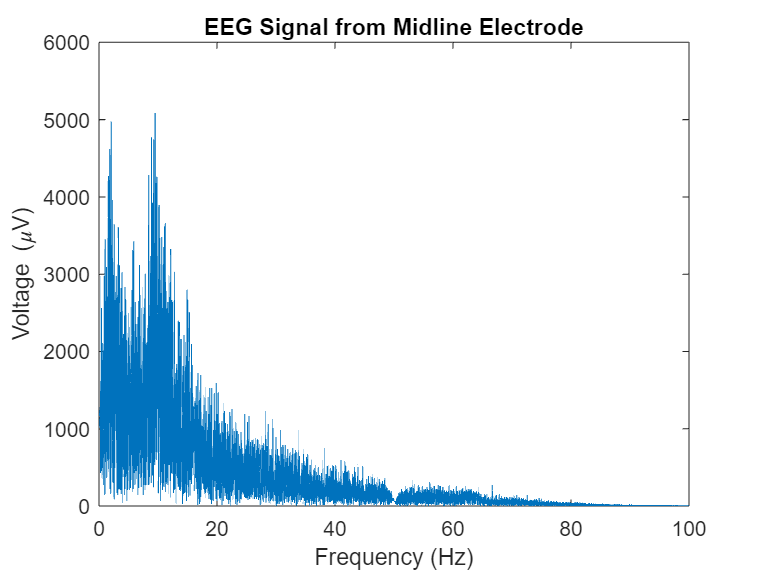


fig2 = figure;
transformed_Cz = fft(Cz);                           % Performing transform
transformed_Cz = abs(transformed_Cz(1:(L*fs/2)));   % Throwing away second half and taking absolute value
f = (0:(L * fs)/2 - 1) / L;                         % Creating frequency vector

plot(f, transformed_Cz); % Plotting the transform in the Frequency domain
title("EEG Signal from Midline Electrode");
xlabel("Frequency (Hz)");
ylabel("Voltage (\muV)");

Variable binning in order to "smooth" our data. Allows the use of "findpeaks" with a better visual representation, rather than simply using the prominence variable. Here are a few options.

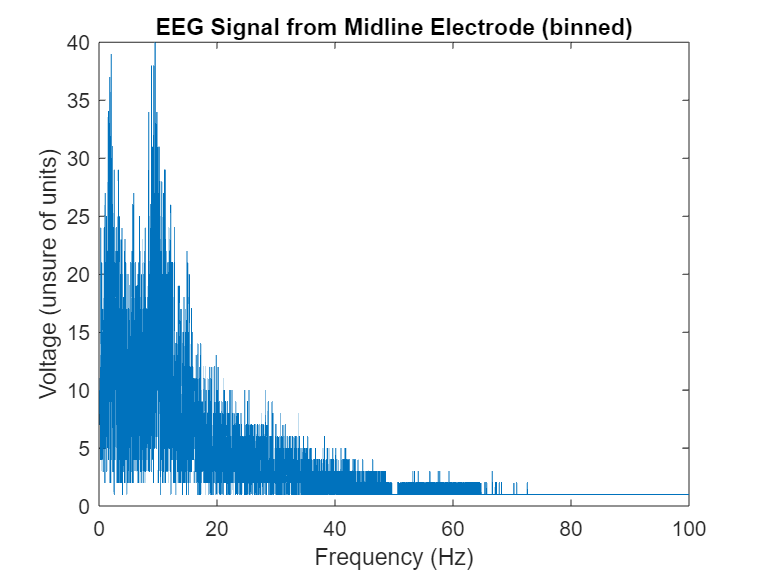

window = ceil(max(f));  % window

num_of_bins = window * 3;
                                            % variable binning, using 200
[binned, ~] = discretize(transformed_Cz, length(transformed_Cz) / num_of_bins); 

b = (1/window)*ones(1,window);
a= 1;
filtered = filter(b, a, transformed_Cz);    % filtering data 

smoothed = smoothdata(transformed_Cz);      % smoothing data

fig3 = figure;
plot(f, binned);
title("EEG Signal from Midline Electrode (binned)");
xlabel("Frequency (Hz)");
ylabel("Voltage (unsure of units)");

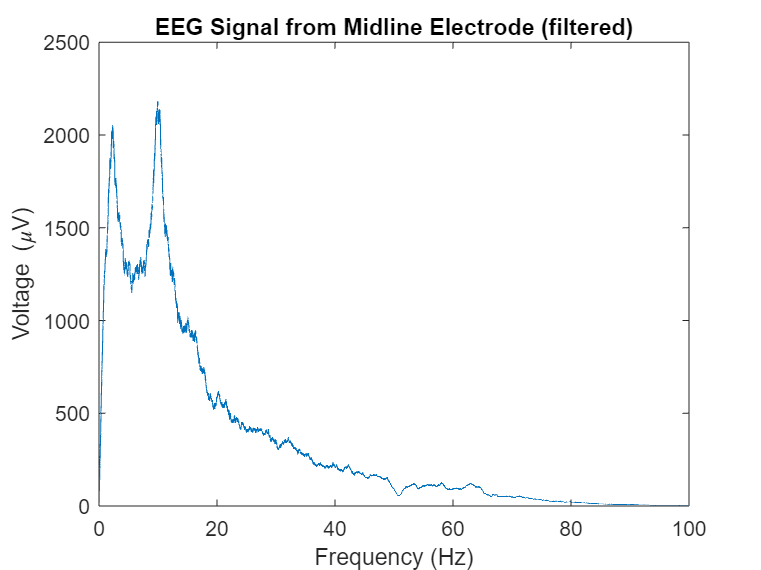


fig4 = figure;
plot(f, filtered);
title("EEG Signal from Midline Electrode (filtered)");
xlabel("Frequency (Hz)");
ylabel("Voltage (\muV)");

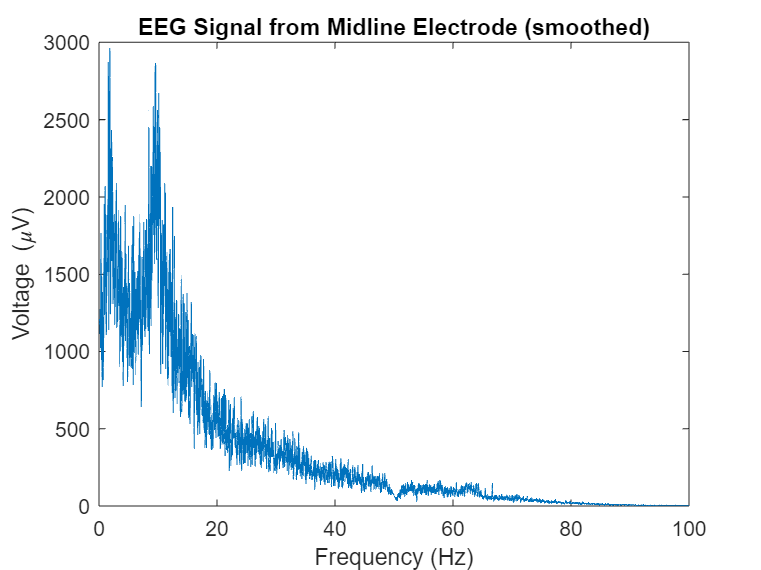


fig5 = figure;
plot(f, smoothed);
title("EEG Signal from Midline Electrode (smoothed)");
xlabel("Frequency (Hz)");
ylabel("Voltage (\muV)");

Performing find peaks to find dominant frequencies with each type of data smoothing

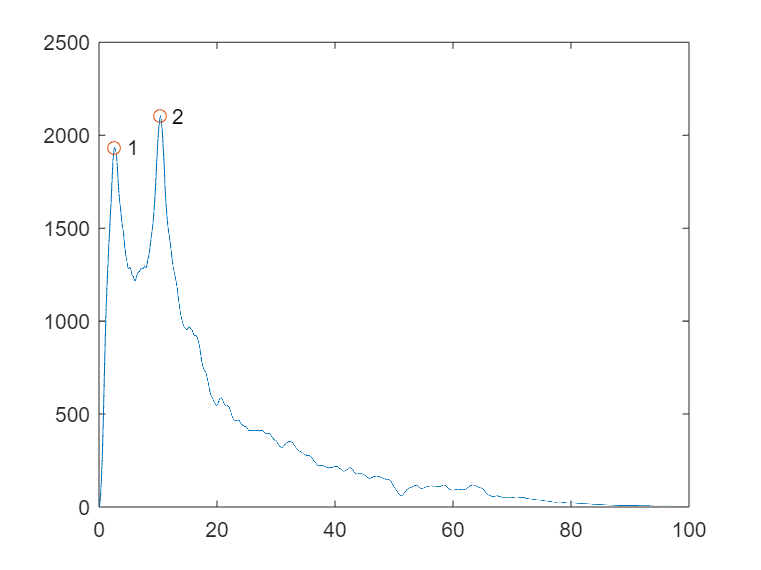

b = (1/window)*ones(1,window);
a = 1;
filtered_2 = filter(b, a, filtered);    % filtering data again

[pks, locs] = findpeaks(filtered_2,'MinPeakProminence',max(filtered_2)/10); % using prominence of arbitrary number
% findpeaks(filtered_2,'MinPeakProminence',max(filtered_2)/10);               % using prominence of arbitrary number
plot(f, filtered_2, (locs/length(filtered_2) * window), pks, 'o');
text((locs/length(filtered_2) * window)+2,pks,num2str((1:numel(pks))'))

disp(locs/length(filtered_2) * window);

    2.6583   10.4083



### References:

(More useful) [https://personal.utdallas.edu/~dlm/3350%20comm%20sys/FFTandMatLab-wanjun%20huang.pdf](https://personal.utdallas.edu/~dlm/3350%20comm%20sys/FFTandMatLab-wanjun%20huang.pdf)

(Less useful) [https://www.mathworks.com/help/matlab/ref/fft.html](https://www.mathworks.com/help/matlab/ref/fft.html)

(Reference) [https://kth.diva-portal.org/smash/get/diva2:1703872/FULLTEXT01.pdf](https://kth.diva-portal.org/smash/get/diva2:1703872/FULLTEXT01.pdf)